# **Minimalbeispiel zur Berechnung der Dispersionskurven**

# Zusätzliche Eingabedaten

Das Beispiel funktioniert nicht als standalone, sondern die Ssteifigkeits- und Massenmatrix, sowie die Knotenmatrix müssen bereits berechnet worden sein. Dabei werden hier folgende Namen verwenden:

Ksys - Steifigkeitsmatrix

Msys - Massenmatrix

InitialNodes - Knotenmatrix, wie aus gmsh exportiert (mit x y z Koordinate)

nBand=6;                  %Anzahl der zu berechnenden Bänder im Dispersionsdiagramm
deltaKxy0=144;              %deltaKxy=pi/deltaKxy0 (Unterteilung der Ränder der Brillouinzone in deltaKxy-Werte
%Festlegung der Bloch-Floquet-Randbedingungen:
PBC0(1,:)=[-0.05, -0.05, 0, -0.05, 0.05, 0];              %[Input line coordinates: x1, y1,z1, x2 ,y2,z2].   Maintain direction for corresponding input/output lines, e.g. top->bottom/left->right.  
PBC0(2,:)=[0.05, -0.05, 0, 0.05, 0.05, 0];              %[Output line coordinates: x1, y1,z1, x2 ,y2,z2].  Maintain direction for corresponding input/output lines, e.g. top->bottom/left->right. 
PBC0(3,:)=[-0.05, -0.05, 0, 0.05, -0.05, 0];              %[Input line coordinates: xx1, y1,z1, x2 ,y2,z2].   Maintain direction for corresponding input/output lines, e.g. top->bottom/left->right.  
PBC0(4,:)=[-0.05, 0.05, 0, 0.05, 0.05, 0];              %[Output line coordinates: x1, y1,z1, x2 ,y2,z2].  Maintain direction for corresponding input/output lines, e.g. top->bottom/left->right. 
Font="CMU Serif";                  %Font for all plots 
FontSize=26;              %Font size for all plots 
AxesLineWidth=1;         %Set default axes line width
LineLineWidth=1;         %Set default line width of all lines within plots

# 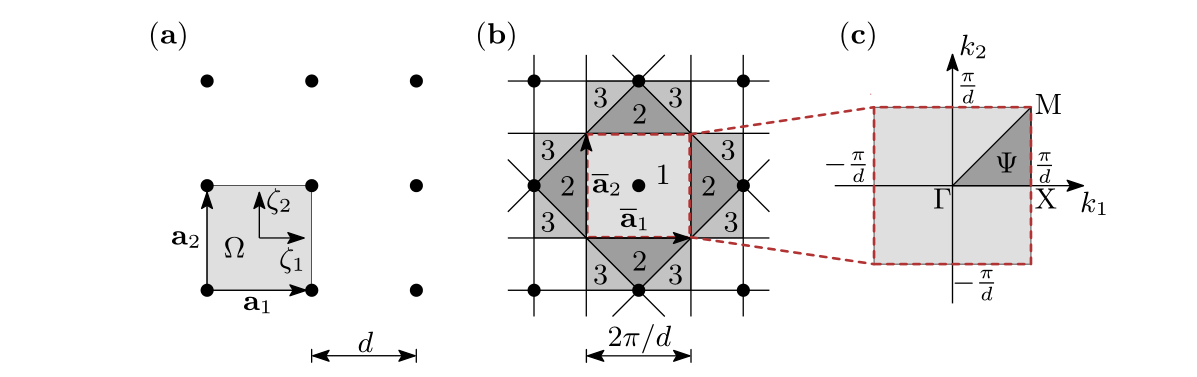

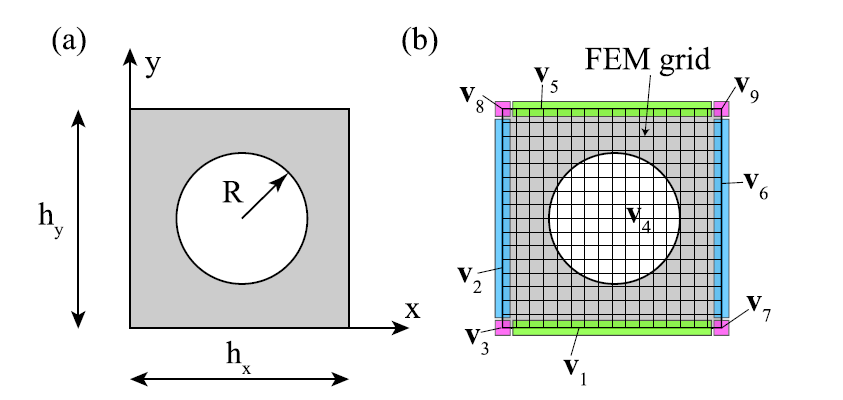

# Berechnung

load("newGmsh.mat");
Nodes = InitialNodes;

minNodeDist=0.0001;
di = 2;

[IdxPBCIn,IdxPBCOut,PBCTrans,BasisVec]=IndexPBC3D(InitialNodes,di,PBC0,minNodeDist);

%IdxPBCIn gibt die jeweiligen Eingangs-Freiheitsgrade an, im Beispiel oben wären das für die x-Richtung v3,v2 und v8.
%IdxPBCOut gibt die jeweiligen Ziel-Freiheitsgrade an, im Beispiel oben wären das für die x-Richtung v7,v6 und v9.    
%PBCTrans gibt die Translation für jeden Knoten auf der linken Seite auf
%die rechte Seite (bzw von unten nach oben) an. 
%BasisVec ist der Basisvektor (Translationsvektor) für die jeweilige Randbedingung, also
%in x-Richtung wäre der Vektor [hx 0 0].

maxBasisVecX=max(max(abs(BasisVec(:,1))));
    maxBasisVecY=max(max(abs(BasisVec(:,2))));
    normdkx=maxBasisVecX/min(maxBasisVecX,maxBasisVecY); 
    normdky=maxBasisVecY/min(maxBasisVecX,maxBasisVecY);
    %Diese Berechnungen (bis Zeile 30) dienen nur der Normierung der Diskretisierung der Brillouin-Zone,
    %sodass alle Ränder auf der Brillouin-Zone gleich diskretisiert werden.
    %Bsp. wenn der Rand Gamma-X und der Rand X-M jeweils in 100 Schritte
    %unterteilt wird, dannn wird der Rand M-Gamma in sqrt(2)*100 Schritte
    %unterteilt, da dieser Rand länger ist. 
    %-----------------------------------------------------------------------------------------------------------------------------------------
    %Calculation of real valued band structure ω(k)
        deltaKx=pi/(deltaKxy0*normdkx);
        deltaKy=pi/(deltaKxy0*normdky);
        deltaKxy=pi/(deltaKxy0*sqrt(normdky^2+normdkx^2));
        %Aufstellen der Vektoren für kx und ky entlang der Brillouin-Zone
        %(s. Abb. oben)
        kx0=[[0:deltaKx:pi]';ones(numel([deltaKy:deltaKy:pi]),1)*pi;[pi-deltaKxy:-deltaKxy:0]'];
        ky0=[zeros(numel([0:deltaKx:pi]),1);[deltaKy:deltaKy:pi]';[pi-deltaKxy:-deltaKxy:0]'];
        if size(BasisVec,1)==1   %GGf. löschen einiger Einträge, falls nur eine Bloch-Randbedinung in x-Richtung vorliegt
        kx0(deltaKxy0+2:end)=[];
        ky0(deltaKxy0+2:end)=[];
        end
        kxy0=[1:1:size(kx0)]; %Nummerierungsvektor von 1 bis Anzahl der Einträge im kx bzw ky Vektor
        nDofPBC=size(Ksys,1)-size(unique(IdxPBCOut),1);      %Anzahl an Freiheitsgraden im reduzierten System (also abzgl. v8, v5, v9, v6, v7)
        fBand=zeros(nBand,size(kx0,1));                      %Preallokation einer Matrix, in die die Eigenfrequenzen pro Berechnungsschritt geschrieben werden
        ABand=zeros(nDofPBC,nBand,size(kx0,1));              %Preallokation einer Matrix, in die die Eigenformen pro Berechnungsschritt geschrieben werden
        parfor kindx=1:size(kx0,1)                           %Schleife zur Berechnung der Dispersionskurven
%         kindx = 1;
        i=sqrt(-1);
        kx=kx0(kindx)+0.01;                                 %Auslesen von kx
        ky=ky0(kindx);                                       %Auslesen von ky
        lambX=exp(sqrt(-1)*kx);                              %Berechnung der Ausbreitungskonstante Lambdax
        lambY=exp(sqrt(-1)*ky);                              %Berechnung der Ausbreitungskonstante Lambday
        [KPBC, MPBC,~] = ApplyBlochBC2D(Ksys,Msys,IdxPBCIn,IdxPBCOut,lambX, lambY,PBCTrans); %Einbau der Randbedingungen mittels Funktion
        [AEig0PBC,LambdaPBC]=eigs(KPBC,MPBC,nBand,'smallestabs');     %Lösen des Eigenwertproblems
        [LambdaPBC, LambdaPBCLoc]=sort(diag(LambdaPBC));     %Sortieren der Lösungen
        OmegaiPBC=sqrt((LambdaPBC)');                        %Berechnung von omega (mit neuer Sortierung)
        fiPBC=OmegaiPBC/(2*pi());                            %Berechnung von f
        AEig0PBC=AEig0PBC(:, LambdaPBCLoc);                  %Umsortierung der Eigenformen              
        fBand(:,kindx)=fiPBC';                               %Abspeichern der Eigenfrequenzen
        ABand(:,:,kindx)=AEig0PBC;                           %Abspeichern der Eigenformen
        end

# Plotten der Dispersionskurven/Bandstruktur

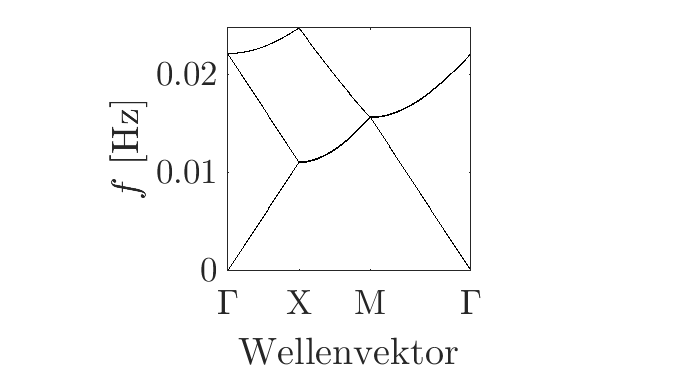

        Xptick=numel([0:deltaKx:pi]');
        Mptick=Xptick+numel([deltaKy:deltaKy:pi]);
figure
LightGrey = [0.8,0.8,0.8];             %Light Grey 
set(gcf, 'Position',  [0, 0, 1920, 1080])
hold on
fBand=abs(fBand);
FreqBands=plot(kxy0,fBand,'k','LineWidth',LineLineWidth);
fBandMin=min(abs(fBand'));
fBandMax=max(abs(fBand'));
fBandMin=fBandMin(2:end);
fBandMax=fBandMax(1:end-1);
fBandDelta=fBandMin-fBandMax;
indBand=find(fBandDelta>10);
for bgi=1:size(indBand,2)
Bandgaps=fill([0 max(kxy0) max(kxy0) 0],[fBandMax(indBand(bgi)) fBandMax(indBand(bgi)) fBandMin(indBand(bgi)) fBandMin(indBand(bgi))],LightGrey);
text(0.25,(fBandMin(indBand(bgi))+fBandMax(indBand(bgi)))/2,[num2str(bgi), '. Bandlücke: ',num2str(fBandMax(indBand(bgi)),'%.0f'),' - ',num2str(fBandMin(indBand(bgi)),'%.0f'),' Hz'],'fontsize',8,'fontName',Font);
end
box on
set(gca,'Layer','top')
pbaspect([1 1 1]);
xlabel('Wellenvektor')
ylabel('$f$ [Hz]','interpreter', 'latex')
figureHandle = gcf;
set(findall(figureHandle,'type','text'),'fontSize',FontSize,'fontWeight','normal','fontName',Font)
set(findall(figureHandle,'type','axes'),'fontsize',FontSize,'fontWeight','normal','fontName',Font)
if size(BasisVec,1)==1
axis([0 max(kxy0) 0 1.0*max(max(abs(fBand)))]);
ax = gca;
ax.XTick = [0,max(kxy0)];    
xticklabels({'\Gamma', 'X'})
else
axis([0 max(kxy0) 0 1.0*max(max(abs(fBand)))]);
xticks([0,Xptick,Mptick,max(kxy0)])
xticklabels({'\Gamma', 'X', 'M','\Gamma'})
% set(gca,'ytick',[])
% set(gca,'yticklabel',[])
end
hold off